# Single Track Model Homogenous Solutions

The system is given by:

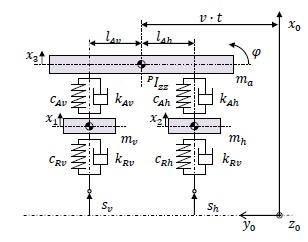 

Since the system is excited, the final DOFs of the system will have a homogenous part and a forced part (particular solution). 

Here, we compute only the homogeneous part of the solution (system solution if there is no external excitation present).

### Linearised Equations of Motion

% System Parameters
f = 4 % DOFs in the system

f = 4

ma = 5 % Sprung Mass (Supported by the suspension)

ma = 5

Jz = 100 % Sprung Mass Mass Moment of Inertia

Jz = 100

mv = 1 % Rear Unsprung Mass

mv = 1

mh = 1 % Front Unsprung Mass

mh = 1

lav = 0.5 % Eccentricity of Rear Wheel from the sprung mass COG

lav = 0.5000

lah = 0.5 % Eccentricity of Front Wheel from the sprung mass COG

lah = 0.5000

cav = 25 % Rear Suspension Spring Stiffness

cav = 25

cah = 25 % Front Suspension Spring Stiffness

cah = 25

kav = 50 % Rear Suspension Damping

kav = 50

kah = 50 % Front Suspension Damping

kah = 50

crv = 10 % Rear Wheel Spring Stiffness

crv = 10

crh = 10 % Front Wheel Spring Stiffness

crh = 10

krv = 10 % Rear Wheel Damping

krv = 10

krh = 10 % Front Wheel Damping

krh = 10


% Mass Matrix
M = [mv,0,0,0;0,mh,0,0;0,0,ma,0;0,0,0,Jz];

% Matrix of Velocity Dependent Forces
P = [kav+krv,0,-kav,lav*kav;0,kah+krh,-kah,-lah*kah;-kav,-kah,kav+kah,kah*lah - kav*lav;lav*kav,-lah*kah,kah*lah-kav*lav,kav*lav*lav + kah*lah*lah];

% Matrix of Position Dependent Forces
Q = [cav+crv,0,-cav,lav*cav;0,cah+crh,-cah,-lah*cah;-cav,-cah,cav+cah,cah*lah - cav*lav;lav*cav,-lah*cah,cah*lah-cav*lav,cav*lav*lav + cah*lah*lah];

### State Space Representation

#### System Matrix

A = [zeros(f,f),eye(f,f);-M\Q,-M\P];

### Modal Matrix and Spectral Matrix using the Eigenvalue representation of the State Space Model

[WW,Lbda] = eig(A); % WW is the modal Matrix (state space eigenvectors as columns) and Lbda is the spectral matrix (diagonal matrix with eigenvalues as the diagonal entries)


### Initial Conditions

w0 = [0,0,0,-1,0,0,0,0]; % -1 radians is the initial pitch of the sprung mass
w0 = w0'

w0 =      0
     0
     0
    -1
     0
     0
     0
     0


#### Integration Constants

intConts = WW\w0

intConts =    0.0000 - 0.0000i
   0.2997 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.5451 - 0.1433i
   0.5451 + 0.1433i
   0.5804 - 0.0000i
  -0.0000 - 0.0000i


### Time Vector

t = linspace(0,100,100);


### Exponential Spectral Matrix

for ii = 1:length(t)
    for jj = 1:length(Lbda)
        for kk = 1:length(Lbda)
            if jj == kk
                eLmbda{ii}(jj,kk) = exp(Lbda(jj,kk)*t(ii)); % Exponential Spectral Matrix corresponding to each time instant
            else 
                eLmbda{ii}(jj,kk) = 0;
            end
        end
    end
end

### Fundamental Matrix

The fundamental matrix is given by:


$$\Phi(t) = \textbf{W}e^{\Lambda t}$$


where

$\textbf{W}:$ Modal Matrix

$\Lambda: $ Spectral Matrix

for ii = 1:length(t)
    phiMat{ii} = WW*eLmbda{ii}*inv(WW);
end

### States

for ii = 1:length(t)
    w{ii} = real(phiMat{ii}*w0);
end

### Computed Degrees of Freedom

for ii = 1:length(t)
    x1(ii) = w{ii}(1);
    x2(ii) = w{ii}(2);
    x3(ii) = w{ii}(3);
    phi(ii) = w{ii}(4);
end

### Plotting the Homogenous Solution

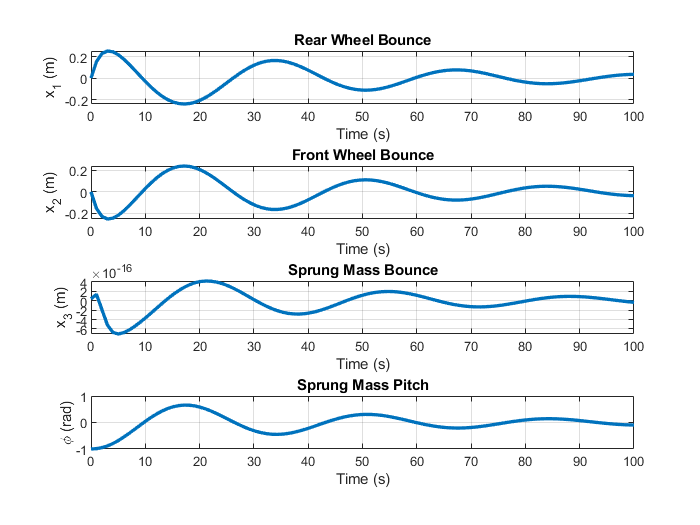

figure
subplot(4,1,1)
plot(t,x1,'linewidth',2)
grid on
title('Rear Wheel Bounce')
xlabel('Time (s)')
ylabel('x_1 (m)')

subplot(4,1,2)
plot(t,x2,'linewidth',2)
grid on
title('Front Wheel Bounce')
xlabel('Time (s)')
ylabel('x_2 (m)')

subplot(4,1,3)
plot(t,x3,'linewidth',2)
grid on
title('Sprung Mass Bounce')
xlabel('Time (s)')
ylabel('x_3 (m)')

subplot(4,1,4)
plot(t,phi,'linewidth',2)
grid on
title('Sprung Mass Pitch')
xlabel('Time (s)')
ylabel('\phi (rad)')